#  Signal Frequency Domain Analysis

## Niusha Mirhakimi

close all
clear
clc

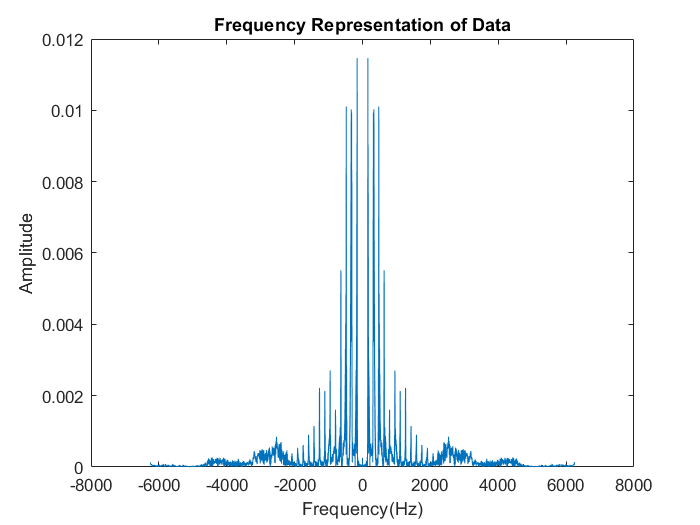


[audio, Fs] = audioread("data.wav");
fourier = fftshift(fft(audio));
f = linspace(-1/2, 1/2, length(audio)) * Fs;
figure
plot(f, abs(fourier) / Fs);
xlabel("Frequency(Hz)");
ylabel("Amplitude");
title("Frequency Representation of Data")

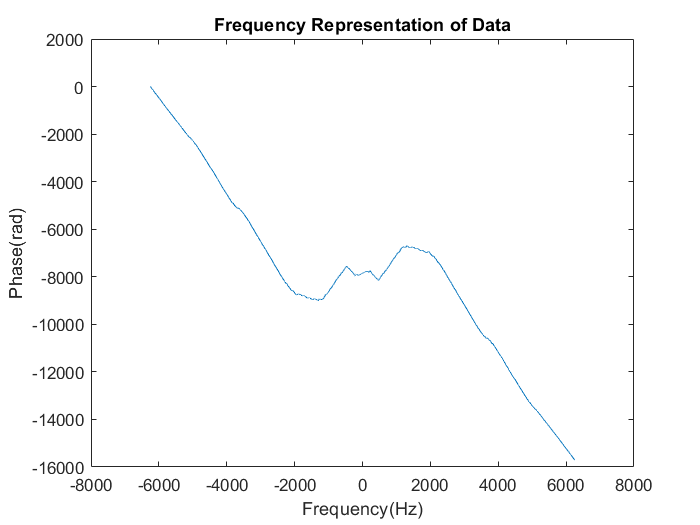

figure
plot(f, phase(fourier));
xlabel("Frequency(Hz)");
ylabel("Phase(rad)");
title("Frequency Representation of Data")

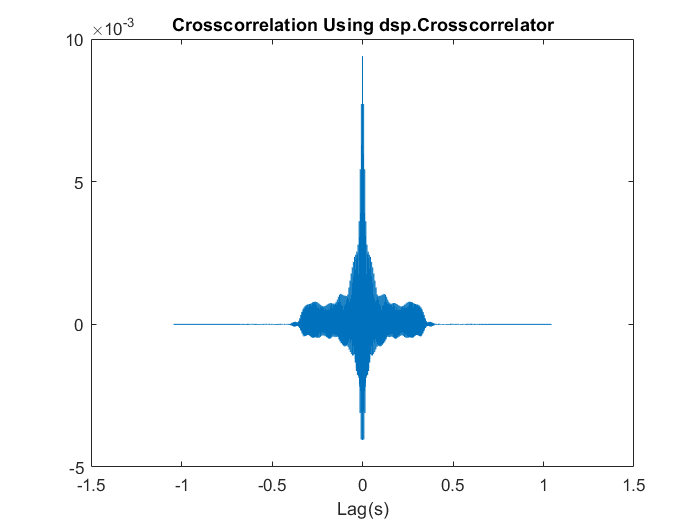


cc1 = crosscorrelation_dsp(audio, audio);
cc1 = cc1 / Fs;
cc2 = crosscorrelation_conv(audio, audio);
cc2 = cc2 / Fs;
lag = linspace(-1, 1, length(cc1)) * (length(audio) - 1) / Fs;
figure
plot(lag, cc1);
xlabel("Lag(s)");
title("Crosscorrelation Using dsp.Crosscorrelator");

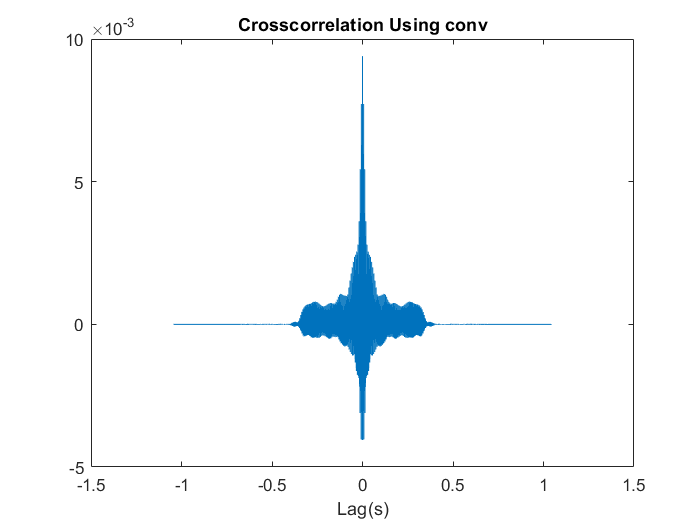

figure
plot(lag, cc2);
xlabel("Lag(s)");
title("Crosscorrelation Using conv")

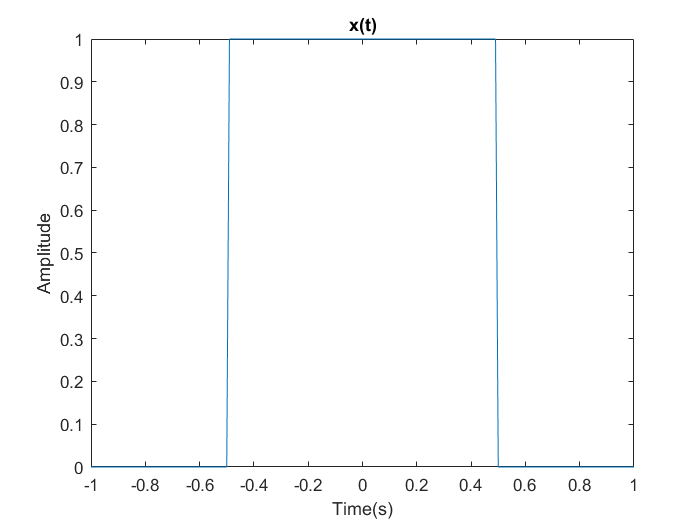

Fs = 100;
PI = @(t) 1 * ((t < 0.5) & (t > -0.5));
t = -1 : 1 / Fs : 1;
x = PI(t);
figure
plot(t, x);
xlabel("Time(s)");
ylabel("Amplitude");
title("x(t)");

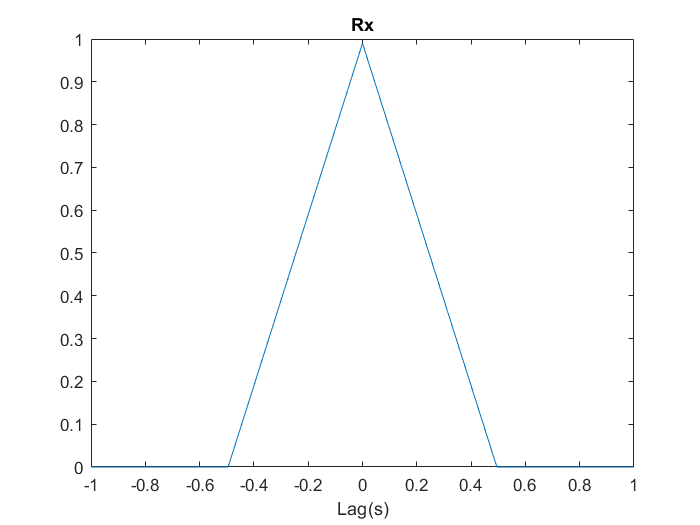

Rx = crosscorrelation_conv(x, x);
Rx = Rx / Fs;
lag = linspace(-1, 1, length(Rx));
figure
plot(lag, Rx);
xlabel("Lag(s)");
title("Rx")

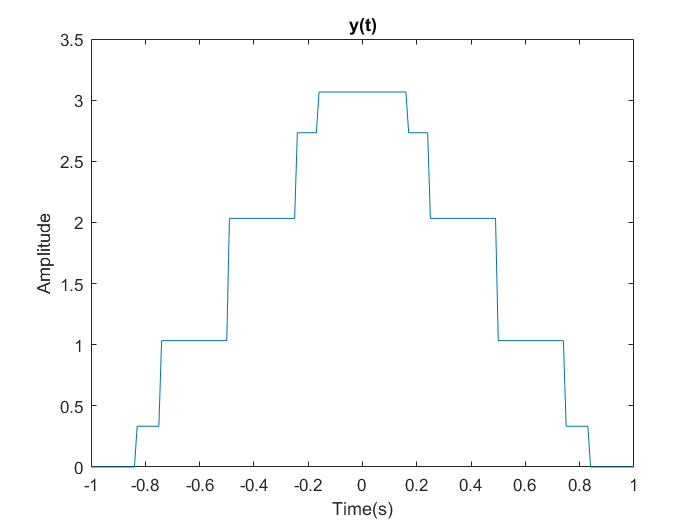


Y = @(m) PI(m) + 0.7 * PI(m - 1 / 4) + 0.7 * PI(m + 1 / 4) ...
    + 1/3 * PI(m - 1 / 3) + 1 / 3 * PI(m + 1 / 3);
y = Y(t);
figure
plot(t, y);
xlabel("Time(s)");
ylabel("Amplitude");
title("y(t)");

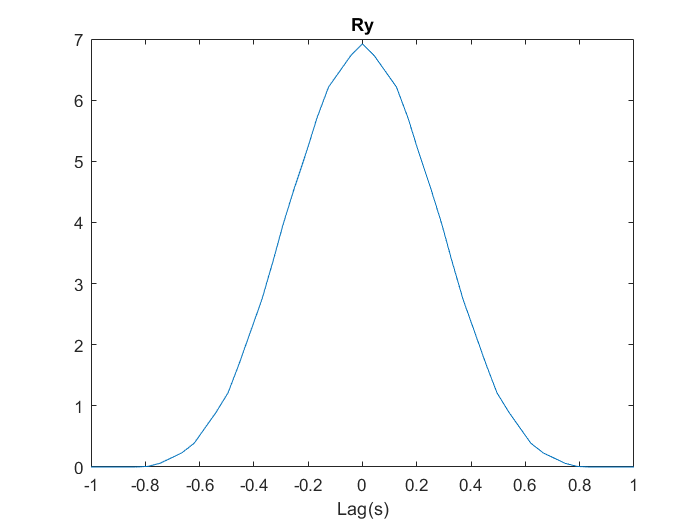

Ry = crosscorrelation_conv(y, y);
Ry = Ry / Fs;
lag = linspace(-1, 1, length(Ry));
figure
plot(lag, Ry);
xlabel("Lag(s)");
title("Ry");

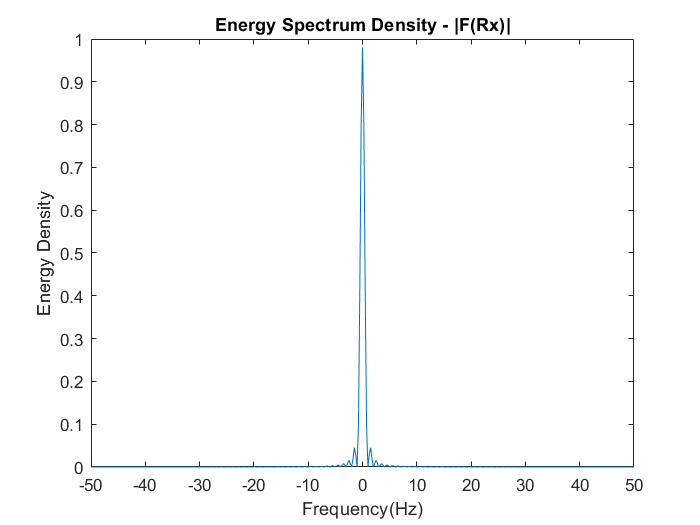

Rx = crosscorrelation_conv(x, x);
Rx = Rx / Fs;
ESD1 = abs(fftshift(fft(Rx))) / Fs;
ESD2 = (abs(fftshift(fft(x))) / Fs) .^ 2;
figure
f1 = linspace(-1 / 2, 1 / 2, length(ESD1)) * Fs;
plot(f1, ESD1);
xlabel("Frequency(Hz)");
ylabel("Energy Density");
title("Energy Spectrum Density - |F(Rx)|");

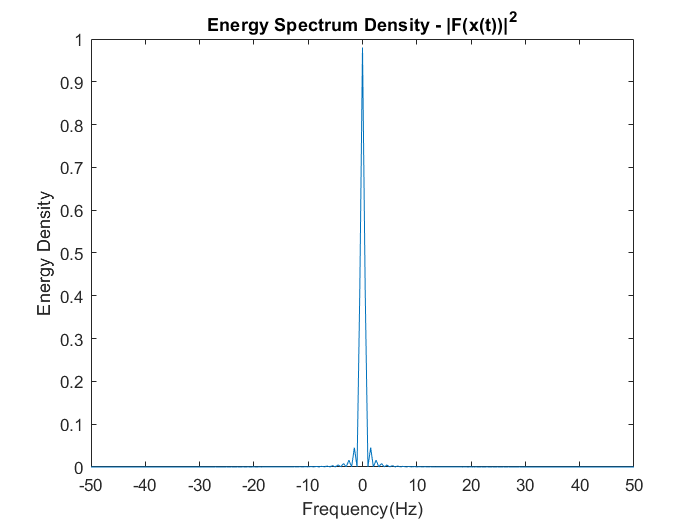

f2 = linspace(-1 / 2, 1 / 2, length(ESD2)) * Fs;
figure
plot(f2, ESD2);
xlabel("Frequency(Hz)");
ylabel("Energy Density");
title("Energy Spectrum Density - |F(x(t))|^2");


Energy1 = sum(ESD1) * Fs / length(ESD1);
"Energy equals:"

ans = "Energy equals:"

Energy1

Energy1 = 0.9900

Energy2 = sum(ESD2) * Fs / length(ESD2);
"Energy equals:"

ans = "Energy equals:"

Energy2

Energy2 = 0.9900

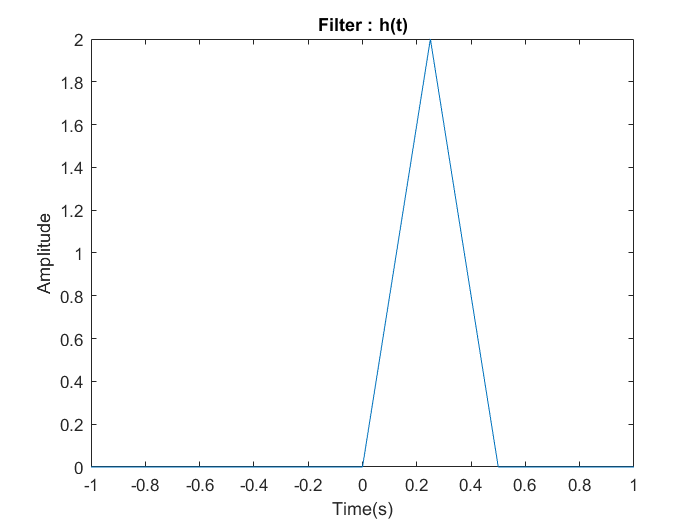

H = @(t) (t > 0 & t < 0.25) .* 8 .* t + (t >= 0.25 & t < 0.5) .* (4 - 8 .* t);
h = H(t);

figure
plot(t, h);
xlabel("Time(s)");
ylabel("Amplitude");
title("Filter : h(t)");

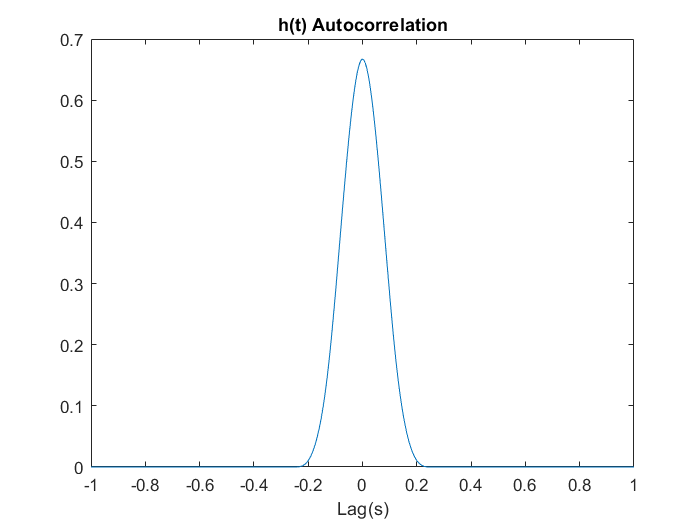


Rh = crosscorrelation_conv(h, h) / Fs;
lag = linspace(-1, 1, length(Rh));
figure
plot(lag, Rh);
xlabel("Lag(s)");
title("h(t) Autocorrelation");

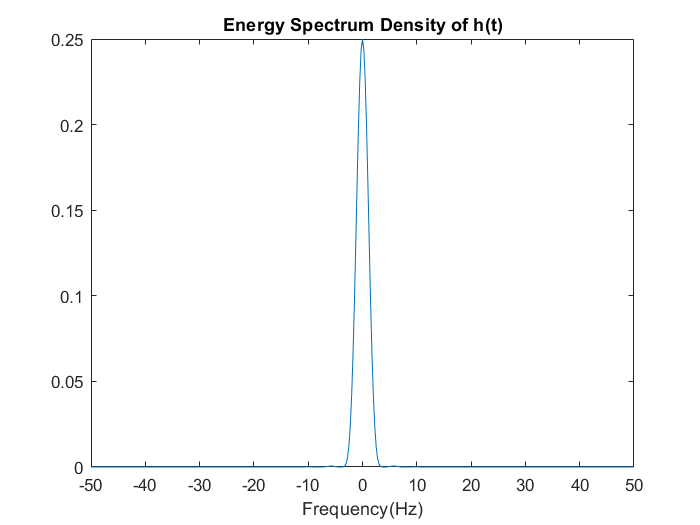


ESD3 = abs(fftshift(fft(Rh))) / Fs;
f3 = linspace(-1/2, 1/2, length(ESD3)) * Fs;
figure
plot(f3, ESD3);
xlabel("Frequency(Hz)");
title("Energy Spectrum Density of h(t)");

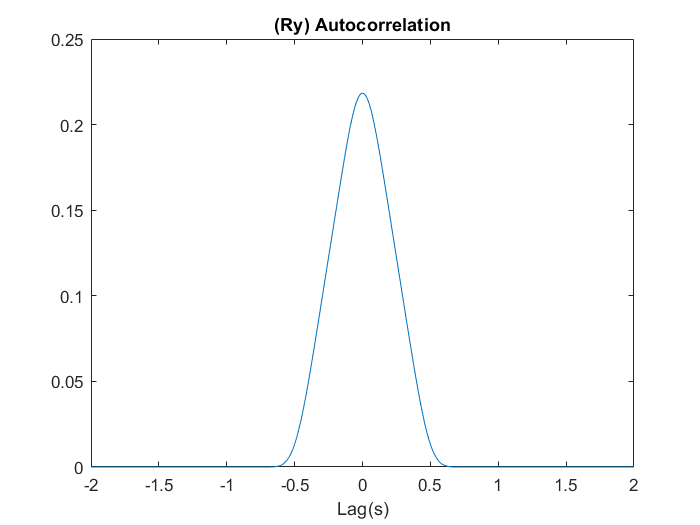


out = conv(x, h) / Fs;
Rout = crosscorrelation_conv(out, out) / Fs;
lag = linspace(-2, 2, length(Rout));
figure
plot(lag, Rout);
xlabel("Lag(s)");
title("(Ry) Autocorrelation");

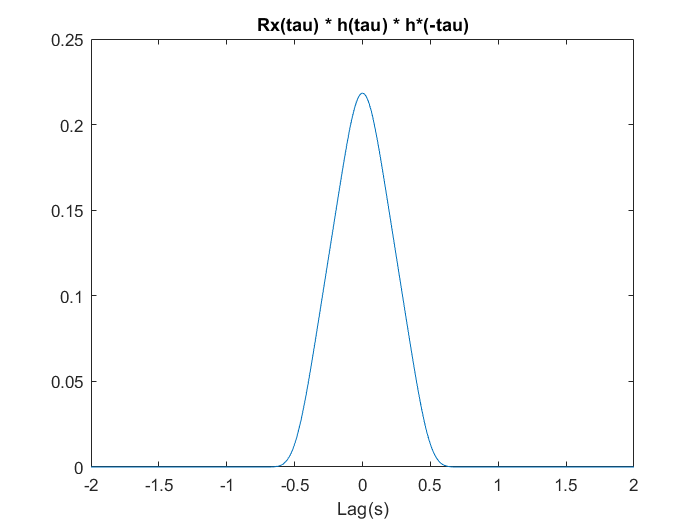



R = conv(conv(Rx, h), conj(h(end : -1 : 1))) / (Fs .^ 2);
lag = linspace(-2, 2, length(R));
figure
plot(lag, R);
xlabel("Lag(s)");
title("Rx(tau) * h(tau) * h*(-tau)")

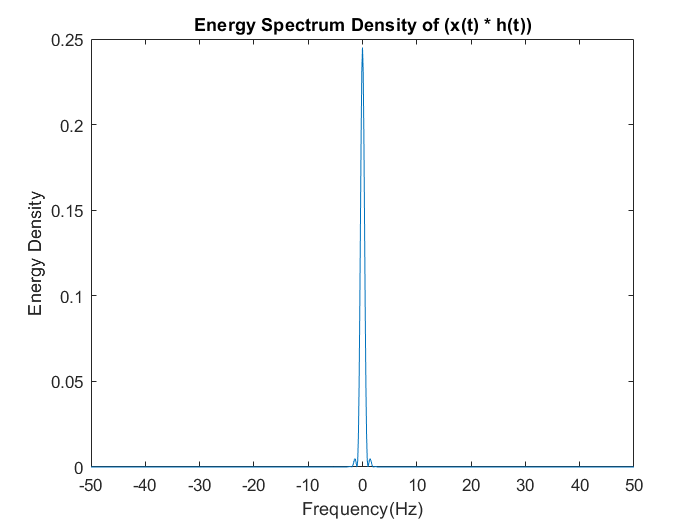


ESD_out = abs(fftshift(fft(Rout))) / Fs;
freq = linspace(-1 / 2, 1 / 2, length(ESD_out)) * Fs;
figure
plot(freq, ESD_out);
xlabel("Frequency(Hz)");
ylabel("Energy Density");
title("Energy Spectrum Density of (x(t) * h(t))");

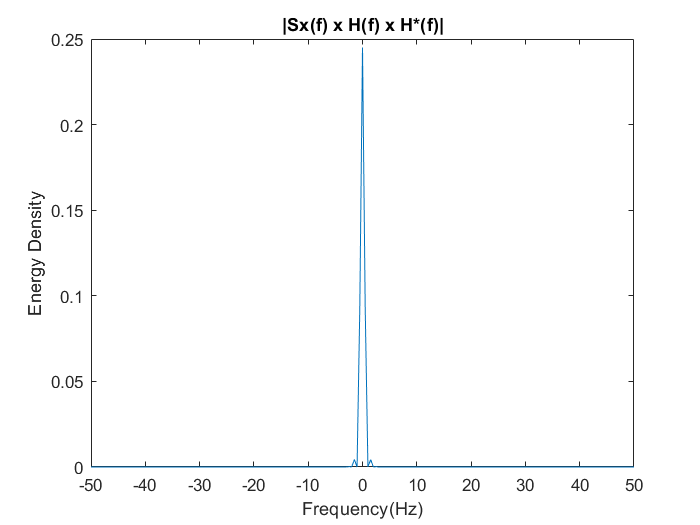



ESD = abs((fftshift(fft(x)) .^ 2) .* fftshift(fft(h)) .* fftshift(fft(conj(h)))) / (Fs .^ 4);
freq = linspace(-1 / 2, 1 / 2, length(ESD)) * Fs;
figure
plot(freq, ESD);
xlabel("Frequency(Hz)")
ylabel("Energy Density");
title("|Sx(f) x H(f) x H*(f)|")